# Create and Customize Compass Plots

Compass plots create arrows emanating from the origin and can be used to visualize cartesian coordinates or imaginary numbers on polar coordinate axes.

### Create Data

Use *linspace *and *pol2cart *in a helper function to generate data for a compass plot.

[u,v] = createData();

### Basic Compass Plot

Visualize a spiral pattern using a compass plot.

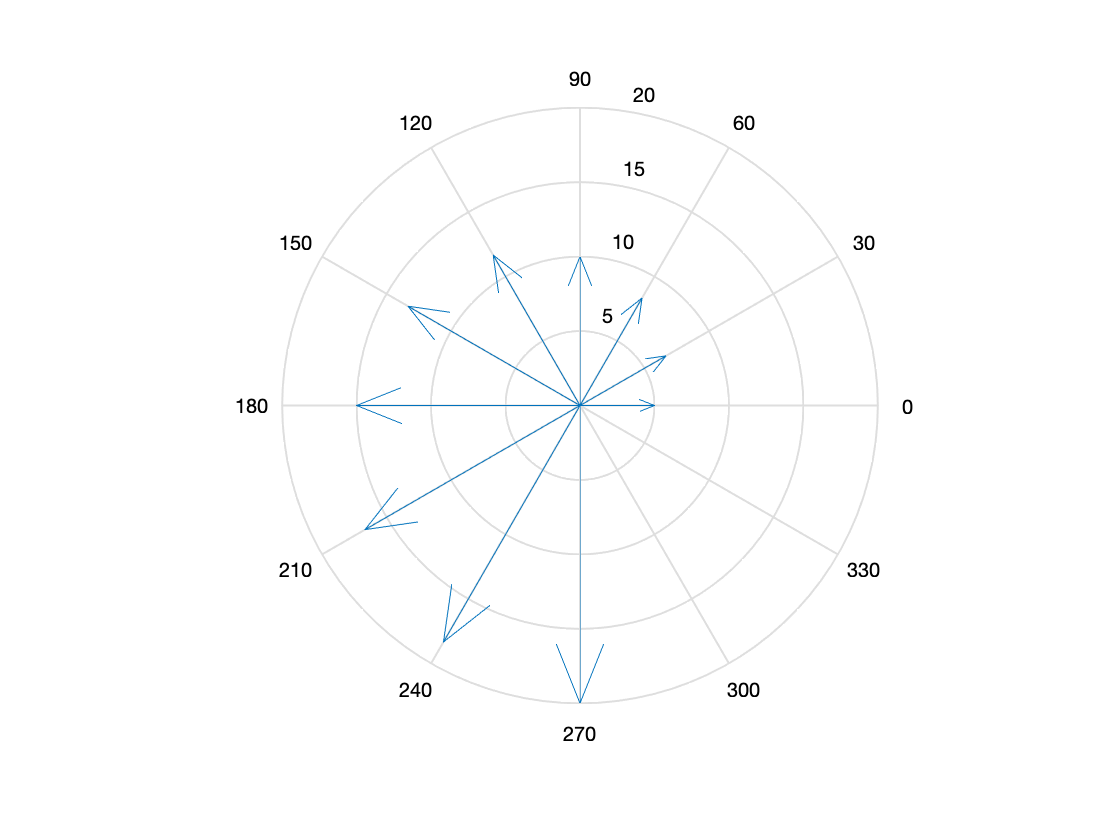

compass(u,v);

## Customization

### Rotate Compass Plot

If it is desired for the theta axis to increase in the clockwise direction, set the *xdir* property of the current axis to *reverse. *To get 0 degrees to point upwards, rotate the theta-axis using the view function.

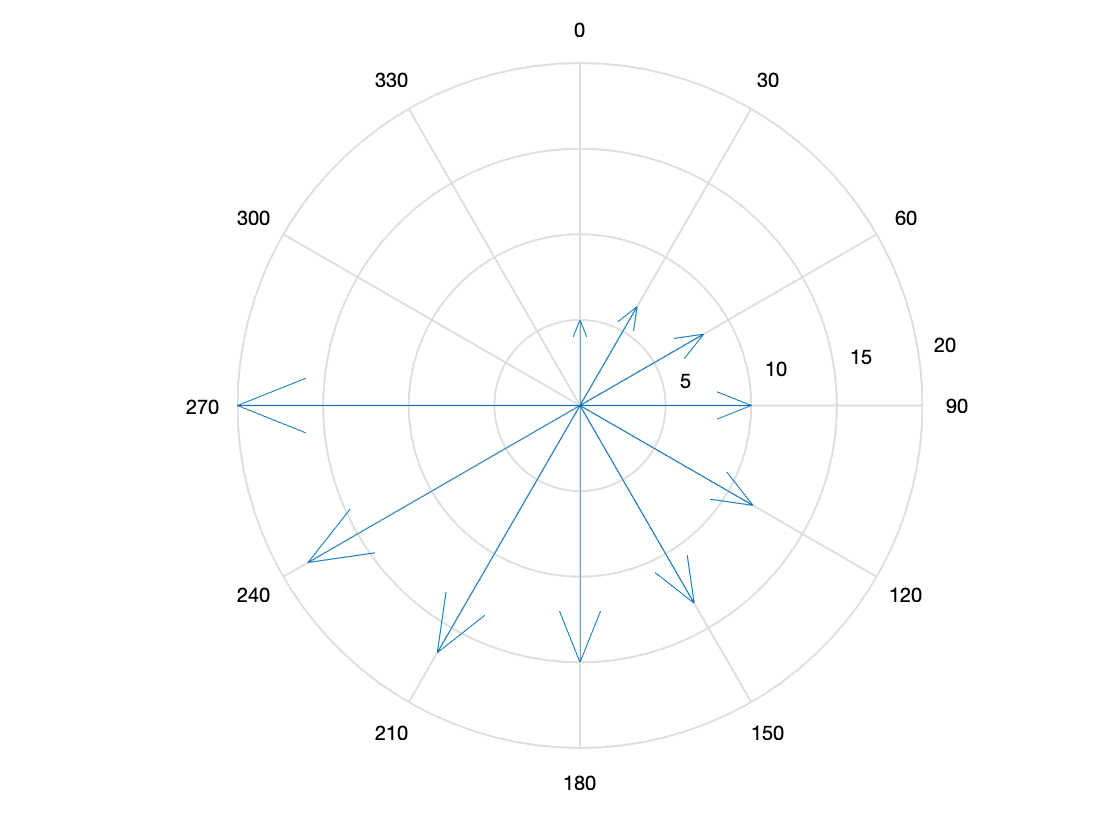

figure
c = compass(u,v);
thetaRotation =90;
set(gca,"xdir","reverse")
view(thetaRotation,90); % Specify the degree of rotation for the theta axis

### Specify Arrow Color

Use the 3rd input to `compass` to specify the arrow color. 

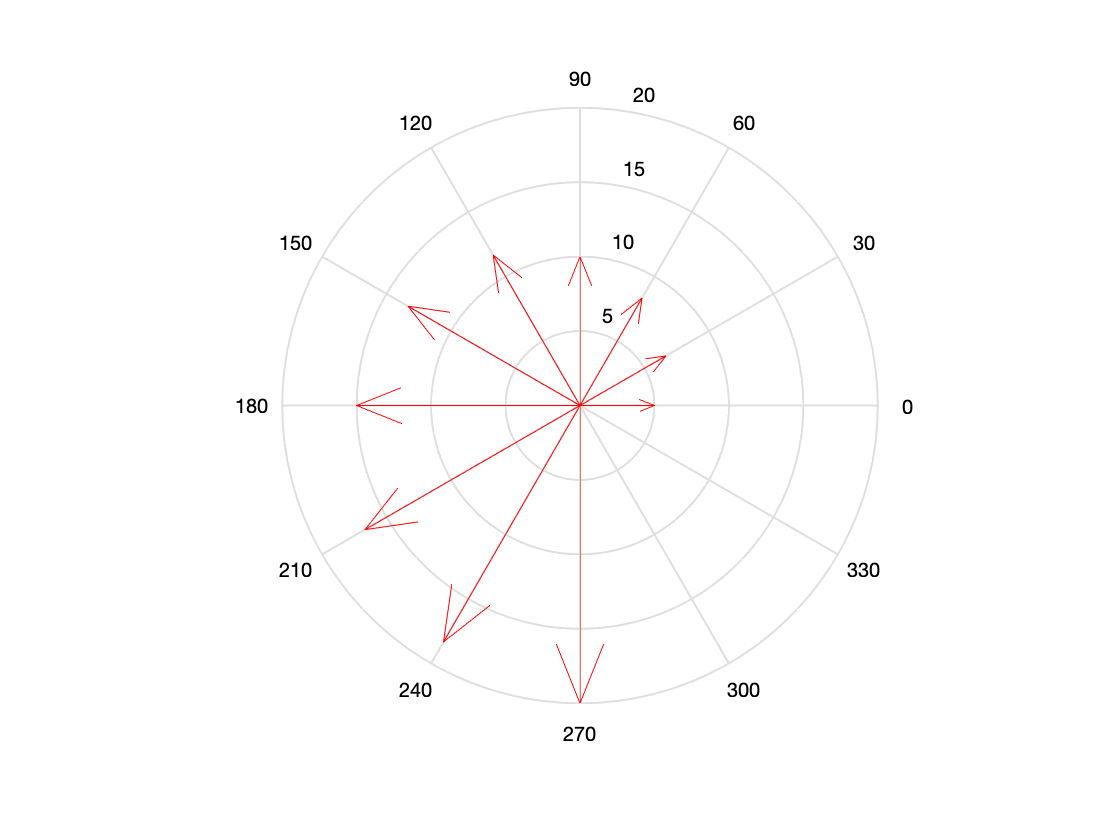

ArrowColor = 'r';
figure
c1 = compass(u,v,...
    ArrowColor);    % Specify arrow color

### Specify Individual Arrow Appearance

Use dot notation to access the *LineWidth *and *Color *Properties of the Line Object generated from a call to `compass`.

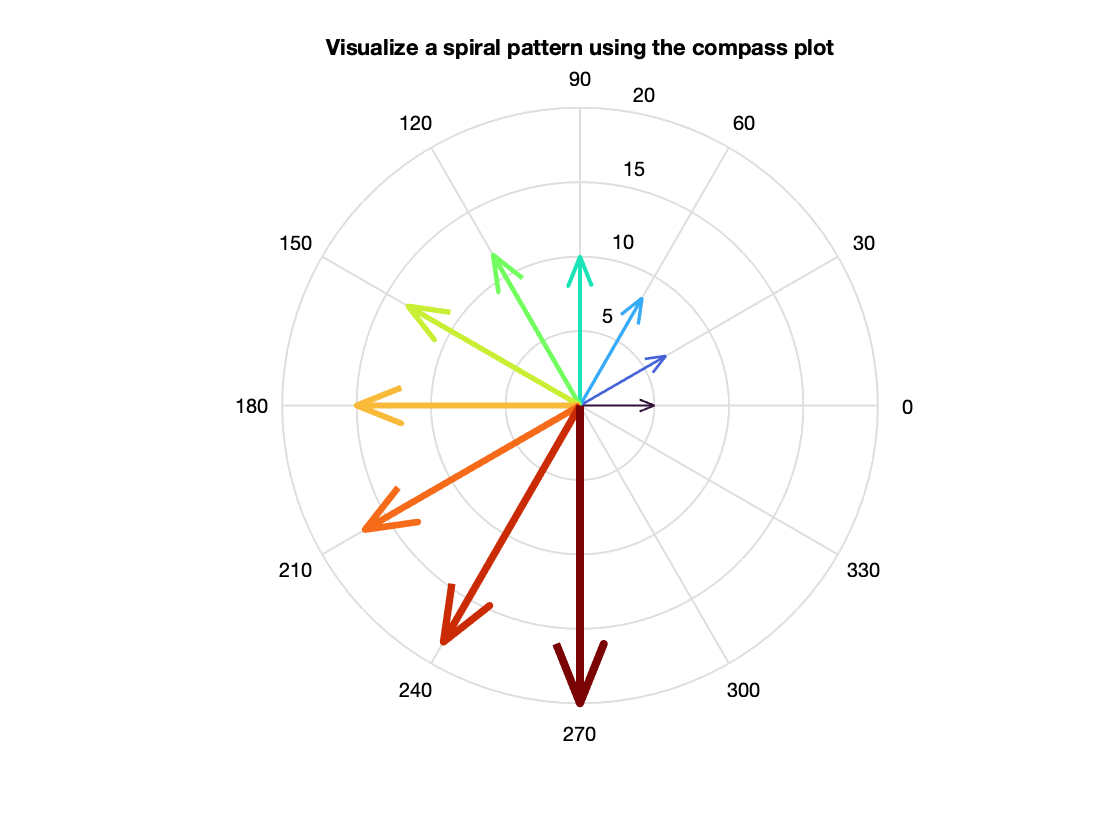

figure
c2 = compass(u,v);
n = length(c2);

LineWidth = linspace(1,4,n);        % Generate vector of increasing LineWidth
Color = colormap(turbo(n));         % Generate vector with ten elements from the turbo colormap

for i = 1:n
    c2(i).LineWidth = LineWidth(i); % Specify LineWidth for each arrow
    c2(i).Color = Color(i,:);       % Specify Color for each arrow
end
title("Visualize a spiral pattern using the compass plot")

## **Additional Information**

### **Get All Line Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Line Object, uncomment the following line of code.

% get(c(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[compass](https://www.mathworks.com/help/matlab/ref/compass.html)

### Helper Function

This function generates u and v data to visualize a compass plot.

function [u,v] = createData()
    th = linspace(0,3*pi/2,10);
    r = linspace(5,20,10);
    [u,v] = pol2cart(th,r);
end

Copyright (c) 2021, The MathWorks, Inc.